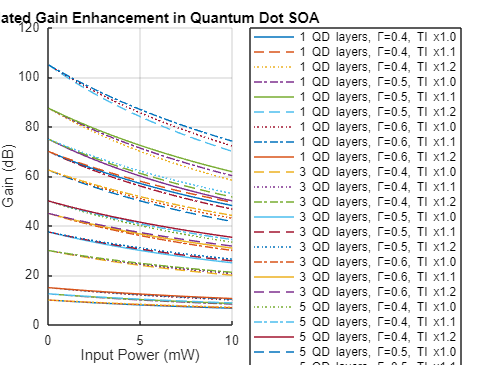

% QD-SOA Gain Enhancement Simulation

% Input power (mW)
Pin = linspace(0.01, 10, 200);

% Baseline parameters
G0_base = 25;      % Small-signal gain (dB)
Psat_base = 20;    % Saturation power (mW)
conf_base = 0.4;   % Baseline confinement factor

% Variables to vary
qd_layers = [1, 3, 5, 7];               % Number of QD layers
conf_factors = [0.4, 0.5, 0.6];         % Confinement factors
ti_boosts = [1.0, 1.1, 1.2];            % Tunnel injection improvement factors

% Create figure
figure;
hold on;
grid on;

% Colors and styles for better clarity
styles = {'-', '--', ':', '-.'};
colorIdx = 1;

for i = 1:length(qd_layers)
    for j = 1:length(conf_factors)
        for k = 1:length(ti_boosts)
            % Updated parameters
            G0 = G0_base * qd_layers(i);
            Psat = Psat_base * ti_boosts(k);
            conf = conf_factors(j);
            
            % Gain model
            Gain = (G0 * conf) ./ (1 + Pin / Psat);
            
            % Plot
            plot(Pin, Gain, ...
                'DisplayName', sprintf('%d QD layers, \\Gamma=%.1f, TI x%.1f', ...
                qd_layers(i), conf, ti_boosts(k)), ...
                'LineStyle', styles{mod(colorIdx-1,length(styles))+1});
            colorIdx = colorIdx + 1;
        end
    end
end

title('Simulated Gain Enhancement in Quantum Dot SOA');
xlabel('Input Power (mW)');
ylabel('Gain (dB)');
legend('Location', 'northeastoutside');